## 仿真数据分析2

rms(out.PID)

ans = 11.5280

rms(out.OF)

ans = 0.5384

rms(out.ADRC)

ans = 2.1123

rms(out.PROPOSE)

ans = 0.2294


max(abs(out.PID))
max(abs(out.OF))
max(abs(out.ADRC))
max(abs(out.PROPOSE))

ans = 2.3067

ans = 0.0340

ans = 2.9753

ans = 0.0540


split_points = [5, 15, 20, 23, 35, 40, 45, 55] * Fs;
segments_length = diff([0; split_points(:); length(out.tout)]);

segments_PID = mat2cell(out.PID, segments_length, 1);
segments_OF = mat2cell(out.OF, segments_length, 1);
segments_ADRC = mat2cell(out.ADRC, segments_length, 1);
segments_PROPOSE = mat2cell(out.PROPOSE, segments_length, 1);

Tab = table();
Tab.Segment = (1:length(segments_PID))';
Tab.RMS_PID = cellfun(@rms, segments_PID);
Tab.PV_PID = cellfun(@max,segments_PID);
Tab.RMS_OF = cellfun(@rms, segments_OF);
Tab.PV_OF = cellfun(@max,segments_OF);
Tab.RMS_ADRC = cellfun(@rms, segments_ADRC);
Tab.PV_ADRC = cellfun(@max,segments_ADRC);
Tab.RMS_PROPOSE = cellfun(@rms, segments_PROPOSE);
Tab.PV_PROPOSE = cellfun(@max,segments_PROPOSE);

disp(Tab);

    Segment    RMS_PID     PV_PID      RMS_OF       PV_OF      RMS_ADRC    PV_ADRC     RMS_PROPOSE    PV_PROPOSE
    _______    _______    ________    ________    _________    ________    ________    ___________    __________

       1       4.1688       2.3067     0.78692     0.034008     1.2812       2.9753       0.1962       0.053965 
       2       1.0549     -0.89578    0.023106     0.022665    0.18852     -0.14979      0.19184       -0.17952 
       3       2.2514      -1.2895     0.18279    -0.049312    0.40071     -0.23327      0.20261       -0.19349 
       4       3.2355      -2.8312     0.23013     -0.20886    0.57326     -0.50209      0.20881       -0.20215 
       5       6.5233      -3.6178     0.43233      -0.2369     1.1567     -0.63712      0.22145       -0.20494 
       6       10.442      -9.4202     0.52152     -0.46495     1.8627      -1.6696      0.23686       -0.22553 
       7       13.117      -11.476     0.61726     -0.52202     2.3603      -2.0548      0.2468

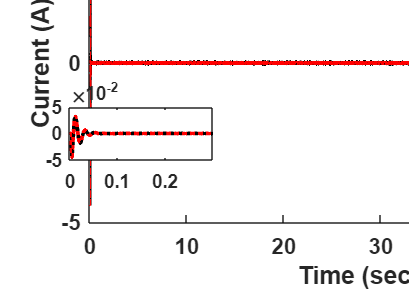

%% 电机电流
ylab1 = 'Current (A)';

choice = 1;
figure()
t = tiledlayout(1,1,'Padding','tight');
t.Units = "centimeters";
t.OuterPosition = [0.5 0.5 12 7];
t.Position = [1.7 1.6 11 6];

nexttile;
p1 = plot(out.tout,out.xreal(:,choice)./k_current,'k','LineWidth',2);
hold on;
p2 = plot(out.tout,out.xhat(:,choice)./k_current,'r-.','LineWidth',1.5);
legend([p1 p2],'actual state','estimated state','box','off');
xlabel('Time (second)','FontWeight','bold');
ylabel(ylab1,'FontWeight','bold');
ylim([-0.05,0.05])
ax = gca; 
ax.FontWeight = 'bold';
ax.FontSize = 12;
ax.YAxis.Exponent = -2;
box off;

a2 = axes('Position',[0.17 0.48 0.35 0.17]);
axes(a2);
p1 = plot(out.tout,out.xreal(:,choice)./k_current,'k','LineWidth',2);
hold on;
p2 = plot(out.tout,out.xhat(:,choice)./k_current,'r:','LineWidth',2);
xlim(a2,[0,0.3]);
a2.FontWeight = 'bold';
a2.FontSize = 10;
a2.YAxis.Exponent = -2;

exportgraphics(gcf,fullfile('figures2', ['obser' num2str(choice) '.pdf']),'ContentType','vector');

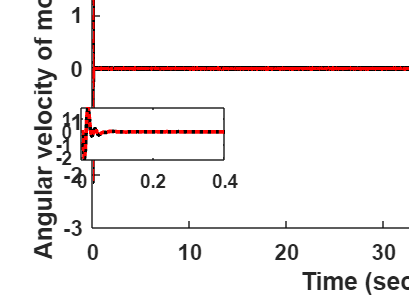

%% 电机转速
ylab1 = 'Angular velocity of motor (rad/s)';

choice = 2;

figure()
t = tiledlayout(1,1,'Padding','tight');
t.Units = "centimeters";
t.OuterPosition = [0.5 0.5 12 7];
t.Position = [1.75 1.5 11 6];

nexttile;
p1 = plot(out.tout,out.xreal(:,choice),'k','LineWidth',2);
hold on;
p2 = plot(out.tout,out.xhat(:,choice),'r-.','LineWidth',1.5);
legend([p1 p2],'actual state','estimated state','box','off');
xlabel('Time (second)','FontWeight','bold');
ylabel(ylab1,'FontWeight','bold');
ylim([-3,3]);
box off;
ax = gca; 
ax.FontWeight = 'bold';
ax.FontSize = 12;

a2 = axes('Position',[0.2 0.48 0.35 0.17]);
axes(a2);
p1 = plot(out.tout,out.xreal(:,choice),'k','LineWidth',2);
hold on;
p2 = plot(out.tout,out.xhat(:,choice),'r:','LineWidth',2);
xlim(a2,[0,0.4]);
a2.FontWeight = 'bold';
a2.FontSize = 10;

exportgraphics(gcf,fullfile('figures2', ['obser' num2str(choice) '.pdf']),'ContentType','vector');

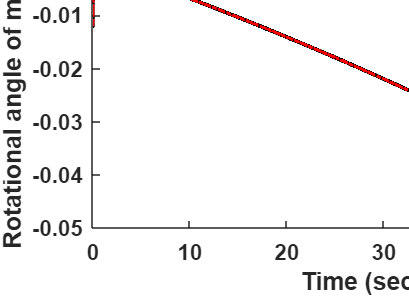

%% 电机转角
ylab1 = 'Rotational angle of motor (rad)';

choice = 3;

figure()
t = tiledlayout(1,1,'Padding','tight');
t.Units = "centimeters";
t.OuterPosition = [0.5 0.5 12 7];
t.Position = [1.75 1.5 11 6];
nexttile;
p1 = plot(out.tout,out.xreal(:,choice)*k_deg2rad,'k','LineWidth',2);
hold on;
p2 = plot(out.tout,out.xhat(:,choice)*k_deg2rad,'r-.','LineWidth',1.5);
legend([p1 p2],'actual state','estimated state','box','off');
ylim([-5e-2,1e-2])
xlabel('Time (second)','FontWeight','bold');
ylabel(ylab1,'FontWeight','bold');
box off;
ax = gca; 
ax.FontWeight = 'bold';
ax.FontSize = 12;

exportgraphics(gcf,fullfile('figures2', ['obser' num2str(choice) '.pdf']),'ContentType','vector');

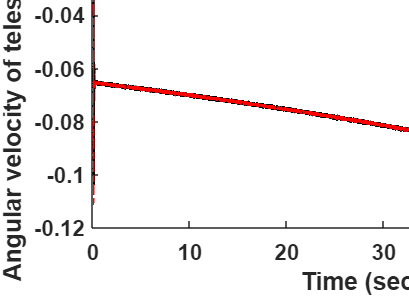

%% 望远镜转速
ylab1 = 'Angular velocity of telescope (rad/s)';

choice = 4;

figure()
t = tiledlayout(1,1,'Padding','tight');
t.Units = "centimeters";
t.OuterPosition = [0.5 0.5 12 7];
t.Position = [1.75 1.5 11 6];

nexttile;
p1 = plot(out.tout,out.xreal(:,choice),'k','LineWidth',2);
hold on;
p2 = plot(out.tout,out.xhat(:,choice),'r-.','LineWidth',1.5);
legend([p1 p2],'actual state','estimated state','box','off');

xlabel('Time (second)','FontWeight','bold');
ylabel(ylab1,'FontWeight','bold');
box off;
ax = gca; 
ax.FontWeight = 'bold';
ax.FontSize = 12;
ax.YAxis.Exponent = -2;

exportgraphics(gcf,fullfile('figures2', ['obser' num2str(choice) '.pdf']),'ContentType','vector');

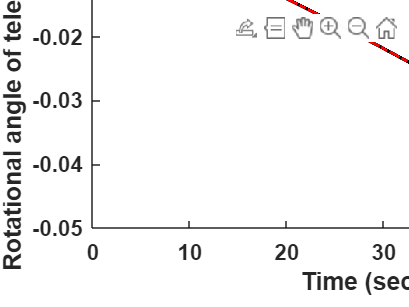

%% 望远镜转角
ylab1 = 'Rotational angle of telescope (rad)';

choice = 5;
figure()
t = tiledlayout(1,1,'Padding','tight');
t.Units = "centimeters";
t.OuterPosition = [0.5 0.5 12 7];
t.Position = [1.75 1.5 11 6];

nexttile;
p1 = plot(out.tout,out.xreal(:,choice)*k_deg2rad,'k','LineWidth',2);
hold on;
p2 = plot(out.tout,out.xhat(:,choice)*k_deg2rad,'r-.','LineWidth',1.5);
legend([p1 p2],'real state','estimation','box','off');
ylim([-0.05 0]);
xlabel('Time (second)','FontWeight','bold');
ylabel(ylab1,'FontWeight','bold');
ax = gca; 
ax.FontWeight = 'bold';
ax.FontSize = 12;
box off;

exportgraphics(gcf,fullfile('figures2', ['obser' num2str(choice) '.pdf']),'ContentType','vector');

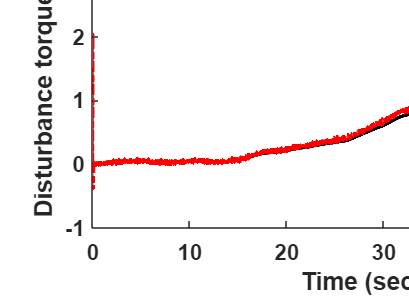

% 扰动观测
choice = 6;

figure()
t = tiledlayout(1,1,'Padding','tight');
t.Units = "centimeters";
t.OuterPosition = [0.5 0.5 12 7];
t.Position = [1.75 1.5 11 6];

nexttile;
hold on;
p1 = plot(out.tout(1:end-1),out.dreal(1:end-1),'k','LineWidth',2);
p2 = plot(out.tout(1:end-1),out.dhat(1:end-1),'r-.','LineWidth',1.5);

legend([p1 p2],'real state','estimation','box','off');
xlabel('Time (second)','FontWeight','bold');
ylabel('Disturbance torque (N·m)','FontWeight','bold');
ylim([-100 400]);
ax = gca; 
ax.FontWeight = 'bold';
ax.FontSize = 12;
ax.YAxis.Exponent = 2;

exportgraphics(gcf,fullfile('figures2', ['obser' num2str(choice) '.pdf']),'ContentType','vector');

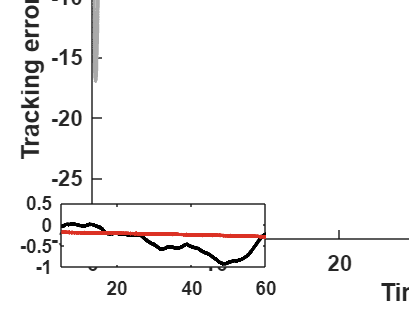

%% 跟踪误差对比图
figure()
t = tiledlayout(1,1,'Padding','tight');
t.Units = "centimeters";
t.Position = [1.75 1.5 14 8];

nexttile;
hold on;
p1 = plot(out.tout,out.PID,'k-','LineWidth',2,'Color',[170,170,170]/255);

p3 = plot(out.tout,out.OF,'k-','LineWidth',2);
p2 = plot(out.tout,out.ADRC,'k-.','LineWidth',2,'Color',[100,100,100]/255);
p4 = plot(out.tout,out.PROPOSE,'-','LineWidth',1.5,'Color',[219, 49, 36, 0.8*255]/255);

ylim([-30 5]);
xlabel('Time (second)','FontWeight','bold');
ylabel('Tracking error (arcsec)','FontWeight','bold');
legend([p1,p2,p3,p4],'PID','ADRC','DOFC','Proposed Method','box','off','Orientation','horizontal','Location','northoutside');
ax = gca; 
ax.FontWeight = 'bold';
ax.FontSize = 12;
box off;

a2 = axes('Position',[0.15 0.16 0.5 0.2]);
axes(a2);
hold on;
p5 = plot(out.tout,out.OF,'k-','LineWidth',2);
p6 = plot(out.tout,out.PROPOSE,'-','LineWidth',2, 'Color',[219, 49, 36,0.8*255]/255);

xlim(a2,[5,60]);
ylim(a2,[-1,0.5]);
a2.FontWeight = 'bold';
a2.FontSize = 10;
a2.Box = "on";

f = gcf;
f.Units = "centimeters";
f.OuterPosition = [2 2 18 14];

exportgraphics(gcf,fullfile('figures2', 'trackingerror.pdf'),'ContentType','vector');

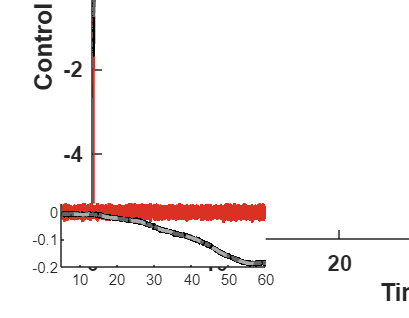

%% 控制力对比图
figure()
t = tiledlayout(1,1,'Padding','tight');
t.Units = "centimeters";
t.Position = [1.75 1.5 14 8];

nexttile;
hold on;
p4 = plot(out.tout,out.u_PROPOSE,'r','LineWidth',2,'Color',[219, 49, 36, 0.7*255]/255);
p3 = plot(out.tout,out.u_OF,'k-','LineWidth',2);
p2 = plot(out.tout,out.u_ADRC,'k-.','LineWidth',2,'Color',[100,100,100]/255);
p1 = plot(out.tout,out.u_PID,'k--','LineWidth',2,'Color',[170,170,170,0.8*255]/255);

xlabel('Time (second)','FontWeight','bold');
ylabel('Control (V)','FontWeight','bold');
legend([p1, p2, p3, p4],'PID','ADRC','DOFC','Proposed Method',...
    'box','off','Orientation','horizontal','Location','northoutside');
ax = gca; 
ax.FontWeight = 'bold';
ax.FontSize = 12;

a2 = axes('Position',[0.15 0.16 0.5 0.2]);
axes(a2);
hold on;
p4 = plot(out.tout,out.u_PROPOSE,'r','LineWidth',2,'Color',[219, 49, 36, 0.7*255]/255);
p3 = plot(out.tout,out.u_OF,'k-','LineWidth',2);
p2 = plot(out.tout,out.u_ADRC,'k-.','LineWidth',2,'Color',[100,100,100]/255);
p1 = plot(out.tout,out.u_PID,'k--','LineWidth',2,'Color',[170,170,170,0.8*255]/255);
xlim(a2,[5,60]);

f = gcf;
f.Units = "centimeters";
f.OuterPosition = [2 2 18 14];

exportgraphics(gcf,fullfile('figures2', 'control effort.pdf'),'ContentType','vector');

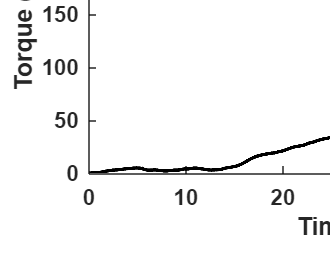

% 扰动
figure()
t = tiledlayout(1,1,'Padding','tight');
t.Units = "centimeters";
t.OuterPosition = [0.5 0.5 12 7];
t.Position = [1.7 1.6 11 6];

nexttile;
hold on;
p1 = plot(out.tout,out.dreal,'k','LineWidth',2);

ylim([0 300]);
xlabel('Time (second)','FontWeight','bold');
ylabel('Torque (N·m)','FontWeight','bold');
legend('Wind disturbance','box','off');
ax = gca; 
ax.FontWeight = 'bold';
ax.FontSize = 12;
box off;
f = gcf;
f.Units = "centimeters";
f.OuterPosition = [2 2 18 14];

exportgraphics(gcf,fullfile('figures2', 'disturbance.pdf'),'ContentType','vector');

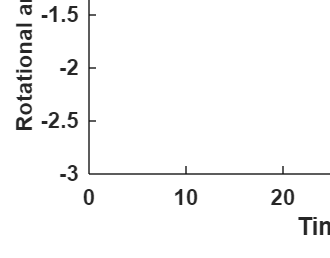

figure()
t = tiledlayout(1,1,'Padding','tight');
t.Units = "centimeters";
t.OuterPosition = [0 0 12 7];
t.Position = [1.7 1.6 11 6];

nexttile;
hold on;
p1 = plot(T_simu',az_pre,'k','LineWidth',2);
p1.Color = [11, 51, 113]/255;
xlabel('Time (second)','FontWeight','bold');
ylabel('Rotational angle (deg)','FontWeight','bold');
ylim([-3,0]);
legend('Desired trajectory','box','off');
ax = gca; 
ax.FontWeight = 'bold';
ax.FontSize = 12;
ax.YLabel.FontSize =12;
ax.Legend.FontSize = 12;
box off;

f = gcf;
f.Units = "centimeters";
f.OuterPosition = [2 1.5 18 14];
exportgraphics(gcf,fullfile('figures2', 'reference.pdf'),'ContentType','vector');